# HW 5

### Code from practice

Task 1

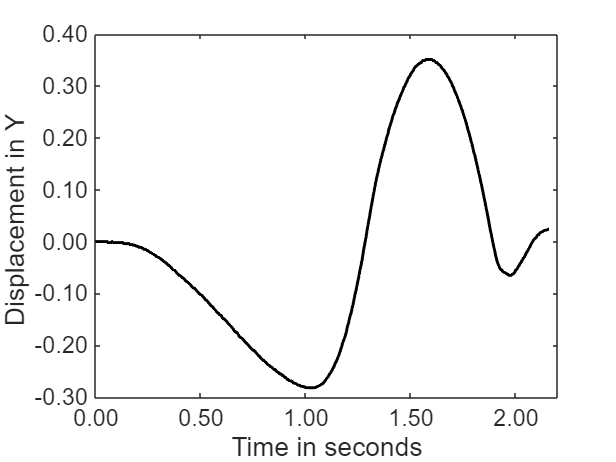

%%
temp = readtable('data.csv'); % This is table
data = table2array(temp); % convert table to array
%data=[t,y]; %first column is time, second column is y displacement in meters
t=data(:,1); % time
y=data(:,2); % displacement
dt=t(2)-t(1);

% Numerični odvod
% doc diff
% Y = [X(2)-X(1) X(3)-X(2) ... X(m)-X(m-1)]
vy=diff(y)/dt; % velocity
ay=diff(vy)/dt; % acceleration

%% no smoothing
close all
figure
plot(t,y,'k',LineWidth=2)
clear ax
ax=gca;
ytickformat('%.2f')
xtickformat('%.2f')
ax.XAxis.FontSize = 16;
ax.YAxis.FontSize = 16;
xlim([0 2.2])
ylabel('Displacement in Y ','FontSize',18);
xlabel('Time in seconds','FontSize',18);

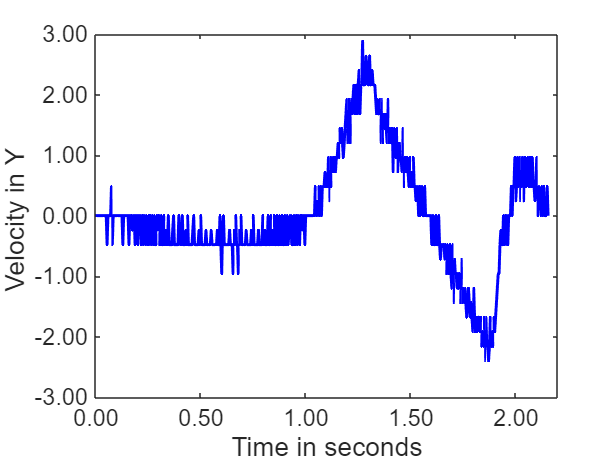


figure
plot(t(1:end-1),vy,'b',LineWidth=2)
clear ax
ax=gca;
ytickformat('%.2f')
xtickformat('%.2f')
ax.XAxis.FontSize = 16;
ax.YAxis.FontSize = 16;
xlim([0 2.2])
ylabel('Velocity in Y ','FontSize',18);
xlabel('Time in seconds','FontSize',18);

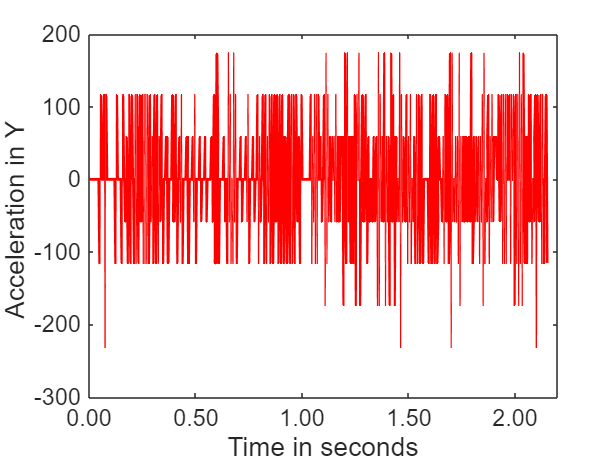


figure
plot(t(1:end-2),ay,'r',LineWidth=2)
clear ax
ax=gca;
ytickformat('%.0f')
xtickformat('%.2f')
ax.XAxis.FontSize = 16;
ax.YAxis.FontSize = 16;
xlim([0 2.2])
ylabel('Acceleration in Y ','FontSize',18);
xlabel('Time in seconds','FontSize',18);

Task 2

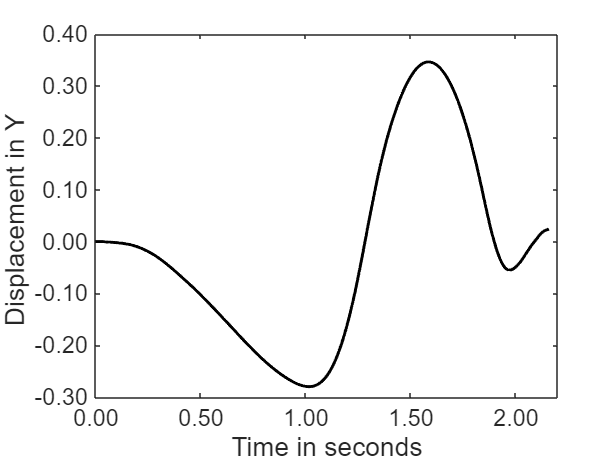

%% SMOOTH %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% ys=smooth(y,30,'sgolay'); % smooth displacement
% vys=diff(ys)/dt; % calculate velocity from smoothed data
% vys=smooth(vys,30,'sgolay'); % smooth it again or not ??????
% ays=diff(vys)/dt;

%%% more user friendly
mywindow=30; % 5 15 30
setmethod='moving'; % 'moving' 'lowess' 'loess' 'sgolay' 'rlowess' 'rloess'
ys=smooth(y,mywindow,setmethod); % smooth displacement
vys=diff(ys)/dt; % calculate velocity from smoothed data
vys=smooth(vys,mywindow,setmethod); % smooth it again or not ??????
ays=diff(vys)/dt; % acceleration
%%%%

function S=MYsmoothFUN(x)
     N=length(x);
     S=NaN(N,1);
     w=[1 2 5 2 1]; % weight
     %check if length is  odd number
     n=ceil(length(w)/2); % we can not start at i=1 and end at i=N
     if mod(length(w),2)==1
         sw=sum(w);
         %for i=3:N-3
         for i=n:N-n
             %             1           2         3           4          5
             S(i)=x(i-2)*w(1)+x(i-1)*w(2)+x(i)*w(3)+x(i+1)*w(4)+x(i+2)*w(5);
             S(i)=S(i)/sw;
         end
     else
        disp('Length of weight vector is not odd! Stop.');
        return
     end

end

figure
plot(t,ys,'k',LineWidth=2)
clear ax
ax=gca;
ytickformat('%.2f')
xtickformat('%.2f')
ax.XAxis.FontSize = 16;
ax.YAxis.FontSize = 16;
xlim([0 2.2])
ylabel('Displacement in Y ','FontSize',18);
xlabel('Time in seconds','FontSize',18);

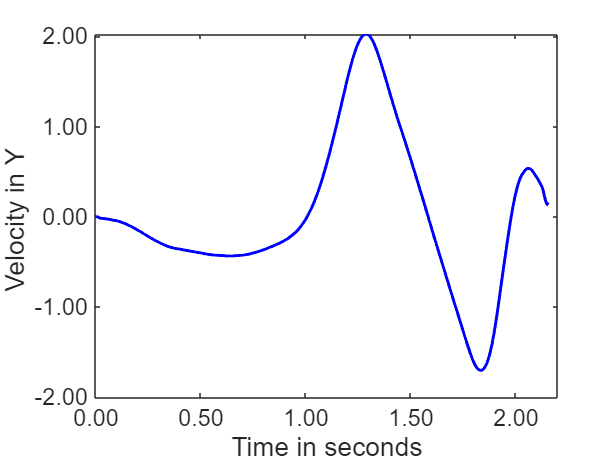


figure
plot(t(1:end-1),vys,'b',LineWidth=2)
clear ax
ax=gca;
ytickformat('%.2f')
xtickformat('%.2f')
ax.XAxis.FontSize = 16;
ax.YAxis.FontSize = 16;
xlim([0 2.2])
ylabel('Velocity in Y ','FontSize',18);
xlabel('Time in seconds','FontSize',18);

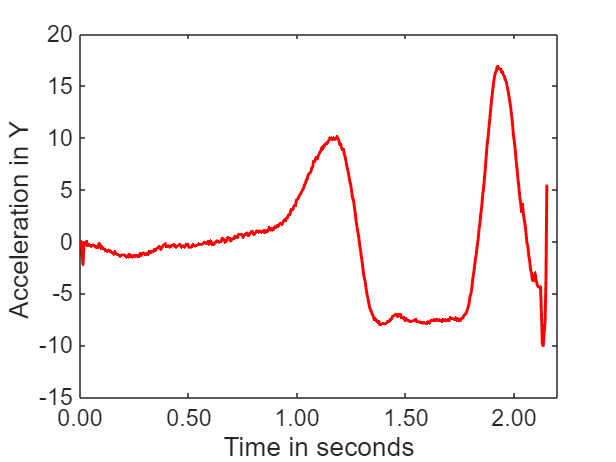


figure
plot(t(1:end-2),ays,'r',LineWidth=2)
clear ax
ax=gca;
ytickformat('%.0f')
xtickformat('%.2f')
ax.XAxis.FontSize = 16;
ax.YAxis.FontSize = 16;
xlim([0 2.2])
ylabel('Acceleration in Y ','FontSize',18);
xlabel('Time in seconds','FontSize',18);

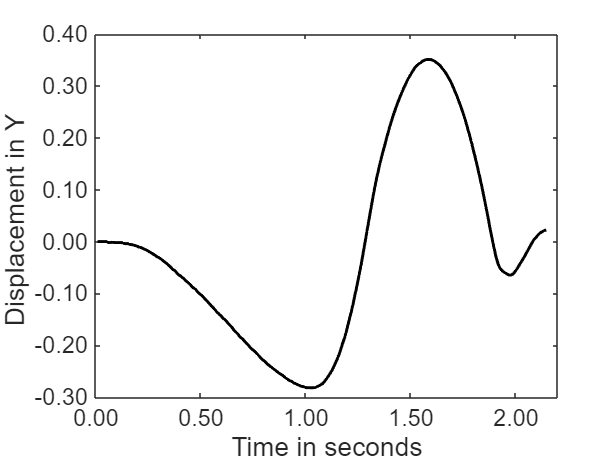


%% weighted smooth user defined function
% 1 2 5 2 1 MYsmoothFUN

ys=MYsmoothFUN(y); % smoothing
vys=diff(ys)/dt; % calculate velocity from smoothed data
vys=MYsmoothFUN(vys); % smooth it again or not ??????
ays=diff(vys)/dt; % acceleration

figure
plot(t,ys,'k',LineWidth=2)
clear ax
ax=gca;
ytickformat('%.2f')
xtickformat('%.2f')
ax.XAxis.FontSize = 16;
ax.YAxis.FontSize = 16;
xlim([0 2.2])
ylabel('Displacement in Y ','FontSize',18);
xlabel('Time in seconds','FontSize',18);

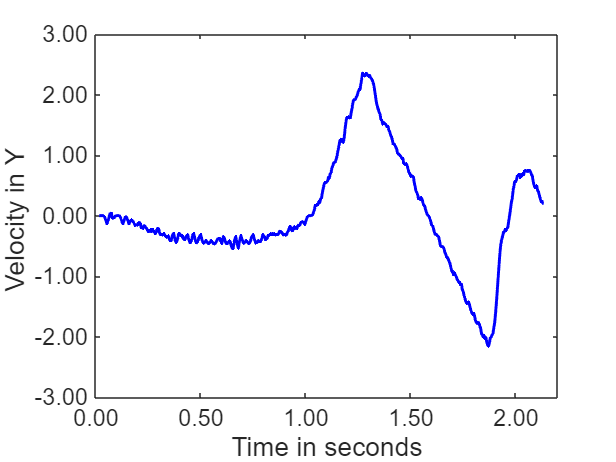


figure
plot(t(1:end-1),vys,'b',LineWidth=2)
clear ax
ax=gca;
ytickformat('%.2f')
xtickformat('%.2f')
ax.XAxis.FontSize = 16;
ax.YAxis.FontSize = 16;
xlim([0 2.2])
ylabel('Velocity in Y ','FontSize',18);
xlabel('Time in seconds','FontSize',18);

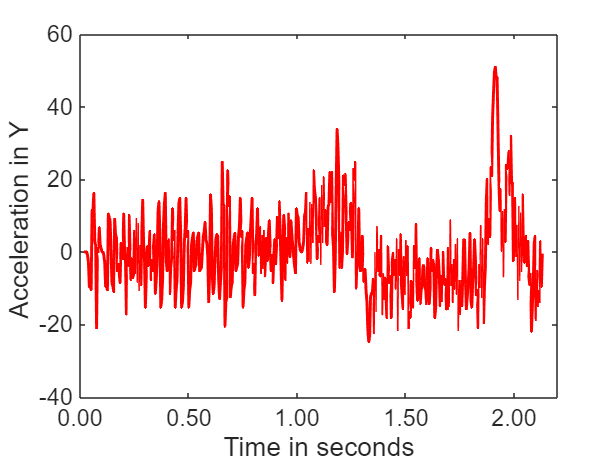


figure
plot(t(1:end-2),ays,'r',LineWidth=2)
clear ax
ax=gca;
ytickformat('%.0f')
xtickformat('%.2f')
ax.XAxis.FontSize = 16;
ax.YAxis.FontSize = 16;
xlim([0 2.2])
ylabel('Acceleration in Y ','FontSize',18);
xlabel('Time in seconds','FontSize',18);

### Homework

Function

%% 
function s = FibSmooth(y, windowSize)
    % test for valid input
    if mod(windowSize, 2) == 0 || windowSize < 3
        error('Window size must be an odd number.');
    end

    % geneation of the sequence
    fibonacciWeights = zeros(1, windowSize);
    fibonacciWeights(1) = 1;
    fibonacciWeights(2) = 1;
    for i = 3:windowSize
        fibonacciWeights(i) = fibonacciWeights(i-1) + fibonacciWeights(i-2);
    end
    % fibonacciWeights % uncomment for debugging -> should return a
                       % fibonacci sequence without 0 and of lenght
                       % specified by user

    [maxValue, maxIndex] = max(fibonacciWeights);

    flipedFibo = fliplr(fibonacciWeights);
    
    finalFibo = zeros(1, length(fibonacciWeights) + length(flipedFibo) - 1);
    finalFibo(1:maxIndex) = fibonacciWeights(1:maxIndex);
    finalFibo(maxIndex+1:maxIndex+length(flipedFibo)-1) = flipedFibo(2:end);
    finalFibo(maxIndex) = maxValue;
    % finalFibo % uncomment for debugging -> should return array of nums
                % that flips at the highest number

    finalFibo = finalFibo / sum(finalFibo);

    s = conv(y, finalFibo, 'same');
end


Plots

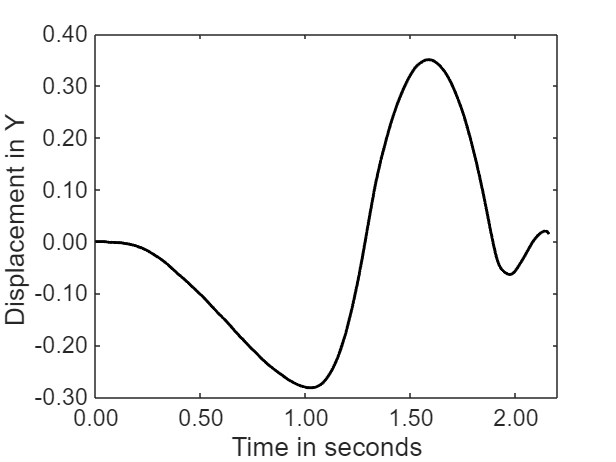

% weighted smooth user defined function (LOG) FIBONACCI
win=999;
ys=FibSmooth(y,win); % window size is the input !!!!!
vys=diff(ys)/dt; % calculate velocity from smoothed data
vys=FibSmooth(vys,win); % smooth it again or not ??????
ays=diff(vys)/dt;

figure
plot(t,ys,'k',LineWidth=2)
clear ax
ax=gca;
ytickformat('%.2f')
xtickformat('%.2f')
ax.XAxis.FontSize = 16;
ax.YAxis.FontSize = 16;
xlim([0 2.2])
ylabel('Displacement in Y ','FontSize',18);
xlabel('Time in seconds','FontSize',18);

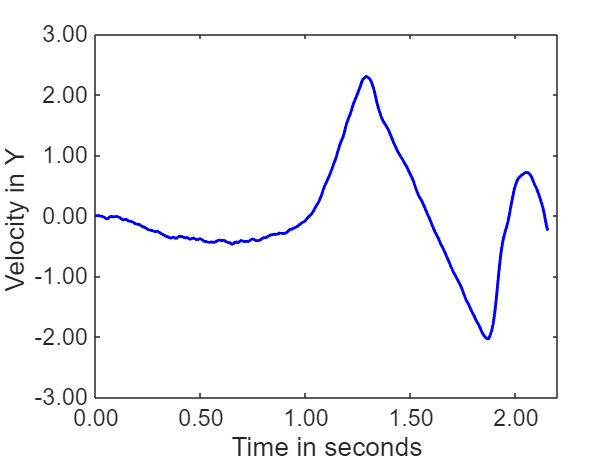

figure
plot(t(1:end-1),vys,'b',LineWidth=2)
clear ax
ax=gca;
ytickformat('%.2f')
xtickformat('%.2f')
ax.XAxis.FontSize = 16;
ax.YAxis.FontSize = 16;
xlim([0 2.2])
ylabel('Velocity in Y ','FontSize',18);
xlabel('Time in seconds','FontSize',18);

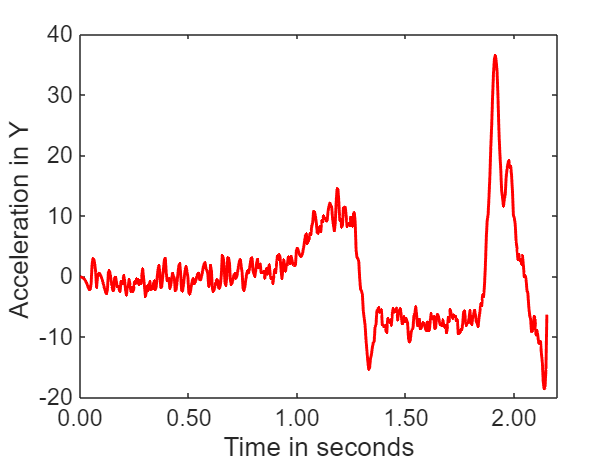

figure
plot(t(1:end-2),ays,'r',LineWidth=2)
clear ax
ax=gca;
ytickformat('%.0f')
xtickformat('%.2f')
ax.XAxis.FontSize = 16;
ax.YAxis.FontSize = 16;
xlim([0 2.2])
ylabel('Acceleration in Y ','FontSize',18);
xlabel('Time in seconds','FontSize',18);

5/11/2024 (improvement): Plot fun for windowSize =  [7, 9, 11, 21, 51]

% Improvement code

